clear

# Numerical Precision in Matlab

### Types of programming languages:

- Strongly Typed --> Java ,C# ..

- Loosely/Dynamically/Weakly Typed --> Python, Matlab

### Numeric Data Types in Matlab:

- Signed & Unsigned Integers.

- Single & Double precision floating point numbers.

## A. Integers in Matlab:

The representation of integers in MATLAB is exact and precise, as long as the size of the integer is within the range that can be represented by the chosen integer class.

 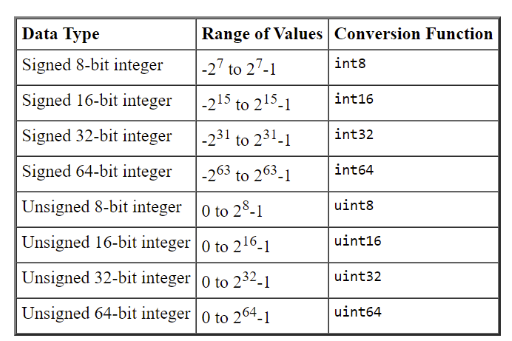

###     Overflow error 

- The largest signed 8-bit integer is 127.

- The extra bits needed to represent the large number overflow out of the available 8-bits to represent the number.

- Difference between the number and its representation is called overflow error.

### intmax('...') , intmin('....')  

- The functions intmax() and intmin() return the maximum and minimum values that can be represented with all types of integer numbers.

- Both  functions take the integer data type as the argument.

### isinteger(argument)

verifies if an argument is integer

### Converting a floating point number to an integer

- If the number being converted to an integer has a fractional part, MATLAB rounds to the nearest integer.

To round a number using a rounding scheme other than the default, MATLAB provides three rounding functions:

- fix(x).

- floor(x).

- ceil(x).

### Arithmetic operations

Arithmetic operations that involve both integers and floating-point numbers always result in a an integer data type.

x = 325 * 4.39; % = 1426.68 exactly


## B. Floating point numbers in Matlab:

- Floating-point numbers = real numbers.

- Floating-point numbers has a fractional component to the right of the decimal point.

%By default, the command window only displays 4 digits to the right of the decimal point.
%This is just a display thing.
%The actual stored number is as precise as its type.



% Regardless of the format settings, the stored number doesn’t change.

#### Floating point numbers representation:

If the number is of a certain size, Matlab reverts to showing it in the command window in exponential form.

- e: is just a letter short for exponent.

- Different than logarithm base e.

%very long floating point number

#### Floating point numbers - Formatting options:

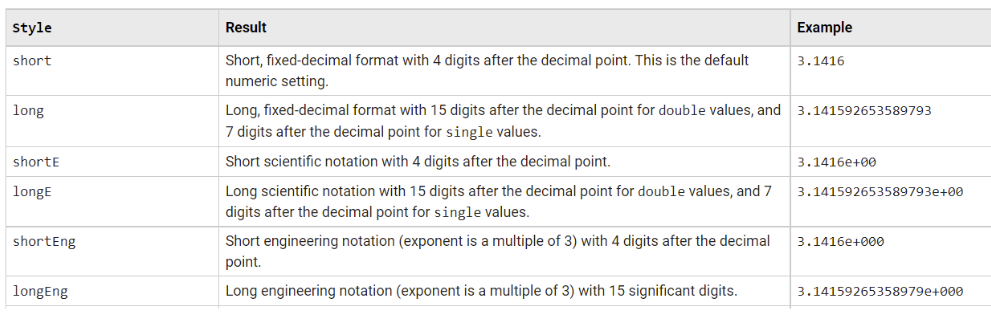

### Engineering notation: 

longEng & shortEng

- converts a very large or very small number into a value between 1 and 1,000 using powers of 10 in increments of 3.

- So the powers of 10 are only the values 0,3, 6, 9, 12, ... or -3, -6, -9, -12, etc.

- A negative power indicates a number smaller than one, whereas a positive power indicates a large number greater than 10.

### Scientific Notation:

shortE & longE

- displays a number as a value between 1 and 9, multiplied by a power of 10.

- A negative power indicates a number smaller than one, whereas a positive power indicates a large number greater than 10.

### Representation of floating point numbers in Matlab:

- MATLAB represents floating-point numbers in either double-precision or single-precision format (both are signed).

- The default floating-point number type in MATLAB is double precision.

- These numbers are stored as exponents.

- Allow them to store extremely large or small numbers with a great deal of precision.

### Double precision floating point:

- MATLAB constructs the double data type according to IEEE Standard 754 for double precision.

-  Any value stored as a double requires 64 bits.

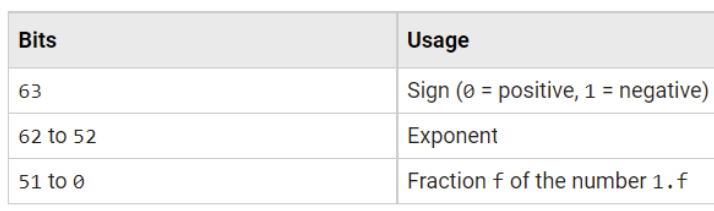

## realmax , realmin 

- The MATLAB functions realmax and realmin return the maximum and minimum values that you can represent with the double data type:

- Numbers larger than realmax or smaller than realmin are assigned the values of positive and negative infinity respectively.

### isfloat(argument)

verifies if an argument is float

### Converting to a Double

-  You can convert other numeric data, characters or strings, and logical data to double precision using the MATLAB function, *double*.

### Single precision floating point:

- MATLAB constructs the single data type according to IEEE Standard 754 for single precision. 

- Any value stored as a single requires 32 bits, formatted as shown in the table.

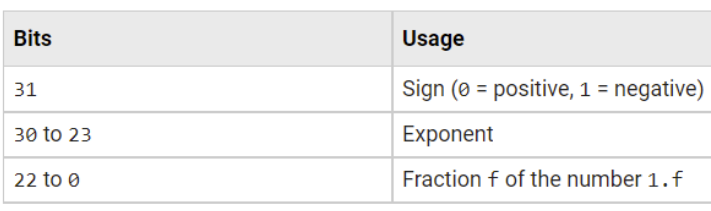

### Converting to a Single

- use the single conversion function to create a single-precision number.

- This value requires only 4 bytes compared with the 8 bytes used to store a double.

### realmax('single') , realmin('single')

- return the maximum and minimum values that you can represent with the single data type.

- Numbers larger than realmax('single') or smaller than realmin('single') are assigned the values of positive and negative infinity respectively.

### Arithmetic operations on floating point numbers

- When operations performed with a `single` class and other class such as `single, double, char` or `logical`*, *the output datatype is `single`.

- When operations performed with a `double` class and other class such as `double, char `or `logical``,` the output datatype is `double. (`Except `Integer` & `Single`).

# Finite precision arithmetic

 Digital representation of numbers with non-zero fractional part, Uses exponential notation → (123.45 * 10^67)

- Representation in Matlab:

- Mantissa between zero and 1.

- First digit right to the decimal point is non zero.

- Ex: 36.3 → 0.363 * 10^2

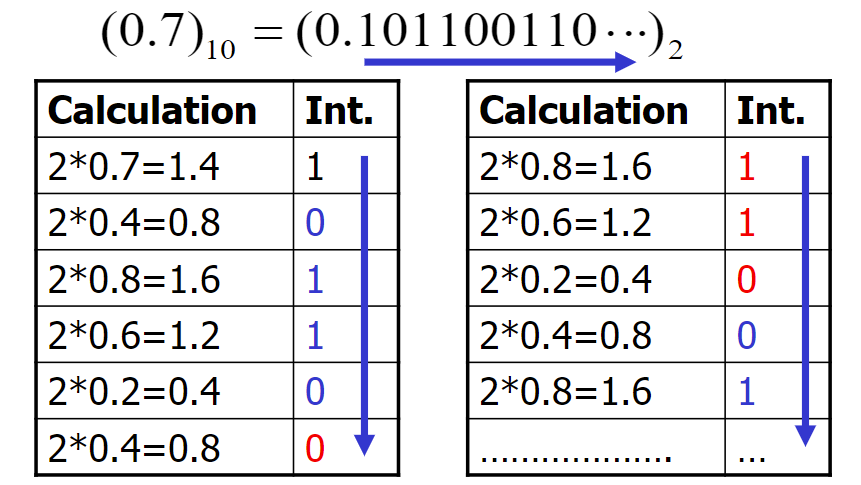

Arithmetics in computers has finite precision.

- Accuracy of mathematical operations is dictated by the least significant bit of the operands’ mantissas.

- The number corresponding to this bit is designated by ε.

- Ex: 1.0 + δ = 1.0, if δ ≤ ε.

- ε in Matlab is a built in variable → eps


% if the error is = eps

%if the error is < eps


### Floating point Comparison Errors:

% The tangant of a number  = ratio of sin(number) / cos(number)




% checking for equality between floating point numbers 
% (Particularly those that are a result of a claculation
% is not a good idea)
% Always take into account finite precision effects.

### Gap between floating point data types:

- Because there are fewer single-precision numbers than double-precision numbers.

- The gaps between the single & double-precision numbers are larger than the gaps between double-precision numbers.

### Accumilated error:

MATLAB accumilates enough error to become noticeable in few calculations.

%2.6 + 0.2





### Error depending on particular numbers:

%2.6 + 0.6 --> no noticable error






% The decimal number 4/3 is not exactly representable as a binary fraction. 






% Small non-zero numbers result in errors in arithmetic  --> sqrt(2)



### Sympolic math not exactly represnetable in numerics 

%Since pi is not really π, it is not surprising that sin(pi) is not exactly zero.



% we could try to approximate 0.1, 0.2 and 0.3 as binary numbers.
% but we may fail as long as we are forced to use a finite number of binary bits in the approximation.
% Sometimes things work other times they don't.





- Always be suspicious from results of arithmetic operations.

- Cross check the results to make sure they make sense.

- Errors can add up in calculations in variety of ways.

- Human error → Find and fix

- Unavoidable errors can happen like finite precision effect.